## Question 5 - Data-Driven Modelling

**For all parts of the question, provide your discussion in bullet points.**

**(a) Consider the following time-series model for the count of vehicles, Y (t), on a road in Bristol. One unit of time is 12 hours, so at t = 0, the total count for 12 hours (7am-7pm) is given, and at t = 1 the count for the following 12 hours is given. Counts are given in 1000s of vehicles, so Y (t) = 5 means 5, 000 vehicles were counted. **

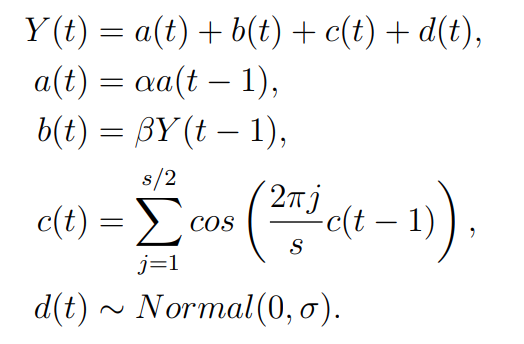

**The parameters of the model have been estimated to take the following values, based on observational data: α = 0.99, β = 0.5, s = 4, and σ = 0.1**

% Parameters estimted based on observational data
alpha = 0.99;
beta = 0.5;
s = 4;
sigma = 0.1;

**(i) Describe the dynamics produced by this model for the initial condition Y (0) = 0, a(0) = 0.75, c(0) = 0.5. Include a sketch/plot in your answer.**

% The number of uses of the equation necessary to produce a full year's
% worth of data - inclusive
CyclesInYear = 365*2+2;

% Setting up the necessary arrays for time series model for count of
% vehicles
Y = zeros(CyclesInYear,1);
a = zeros(CyclesInYear,1);
b = zeros(CyclesInYear,1);
c = zeros(CyclesInYear,1);
Norm = makedist('Normal','mu',0,'sigma',sigma);
d = zeros(CyclesInYear,1);

% Setting the inital conditions
Y(1) = 0;
a(1) = 0.75;
c(1) = 0.5;
d(1) = random(Norm);
b(1) = Y(1) - a(1) - c(1) - d(1);

% Calculatio of time series model predictions of vehicle count
for t=2:CyclesInYear
    % Equations used to calcaulte time series model
    a(t) = alpha*a(t-1);
    b(t) = beta*Y(t-1);

    for i=1:s/2 
       c(t) = c(t) + cos((2*pi*i/s)*c(t-1));
    end
    d(t) = random(Norm);
    
    % Calculation of time series model prediction
    Y(t) = a(t) + b(t) + c(t) + d(t);
end

StartDate = datetime(2024,1,1, 7, 0, 0);
EndDate = datetime(2024,12,31, 19, 0, 0);
X = StartDate:hours(12):EndDate;

% Setting up figure
figure;

% Plotting all values obtained by the time-series model
ax1 = subplot(1,2,1);
plot(X,Y*1000)
xlabel("Hour in the year")
ylabel("Number of Vehicles")
title(sprintf("Number of Vehicles counted on a road in Bristol at 7am and" + ...
    "\n7pm between the 1st of January and 31st of December"),"fontsize",10)

% Plotting the final 20 values obtained by the time-series model
ax2 = subplot(1,2,2);
plot(X(CyclesInYear-20:CyclesInYear),Y(CyclesInYear-20:CyclesInYear)*1000)
xlabel("Hour in the year")
ylabel("Number of Vehicles")
title(sprintf("Number of Vehicles counted on a road in Bristol at 7am and" + ...
    "\n7pm between the 21st of December and 31st of December"),"fontsize",10)

set(gcf,'units','inches','position',[0,0,14,6])

The dynamics in this model are as follows:

- Average around 2100 vehicles in a 24 hour period, with typical deivation of around 500. This gives an approximate traffic flow of 175 vehicles per hour over a day, with approximately 233 vehicles per hour during the day (7am to 7pm) and 116 at night (7pm to 7am). This is approximately one vehicle every 15 seconds in the day and 31 seconds at night.

- a is a steadily decreasing positive value that follows an approximately exponential curve while b is much more fluctuating with b staying positive (apart from the inital value) between 0.65 and 1.45 for night and day respectively. c has the values of 0 and 2 after the initial spike, occupying the value of 2 in the day and 0 at night, suggesting the approximate 2000 vehicle difference between night and day. d is a random noise term that doesn't follow a trend.

- The model settles after an initial spike caused by the initial condition of Y(0) = 0 but there are still some large peaks and troughs at seemingly random intervals

- There is no distinction between weekdays and weekends or seasons (i.e. decreased counts during school/university holidays) and it assumes there is no traffic lights, queues or road works.

**(ii) Discuss the usefulness of this model with the given parameter estimates for forecasting and explaining the dynamics of vehicle traffic counts on the road in Bristol, clearly justifying the arguments you make.**

How useful is this model

What are the positives?

- The model is useful for predicting

How are these positives useful?

What are the drawbacks?

- Very low "sampling" - lots of gaps where data has to be interpolated(extrpolated???)

How does this limit the model?

**(b) This questions extends the worked direct demand modelling example on pedestrian traffic data from Melbourne covered in the lab sheet for data-driven modelling.**

**Guideline to allocation of marks for part (b):**

** • Simple answers build on the code and data provided in the lab sheet. **

**• Good answers consider additional data. **

**• Excellent answers start from scratch, obtaining all data from primary sources. **

**• Use a similar spatial and temporal coverage as shown in the lab sheet example, there are no extra marks for considering larger areas or longer time-frames. **

**(i) Develop and implement in code (Python or Matlab) a regression-based direct demand model for central Melbourne pedestrian traffic to forecast traffic on all links of part of the network 2 hours in advance. Provide a clear explanation and rationale for the model you choose, and for any additional data you obtain. **

What data did I obtain?

- The data that I obtained was 

Rationale for data obtained:

- Large amount of data over many years

- Deemed to have not been affected by COVID too much??? due to summer

- datasets are all the same size

What model did I choose?

Rationale for model:

% read in data from pedestrian counters
% hourly counts for 13 counters for 52 days in June and July 2019.

opts = delimitedTextImportOptions("NumVariables", 102);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date", "Hour", "MelbourneCentral", "LonsdaleSt-ElizabethSt(North)",...
"ElizabethSt-LonsdaleSt(South)","MelbourneCentral-ElizabethSt(East)","StateLibrary",...
"LonsdaleSt(South)","Chinatown-SwanstonSt(North)","Chinatown-LtBourkeSt(South)",...
"BourkeSt-RussellSt(West)","BourkeStreetMall(North)","BourkeStreetMall(South)",...
"LittleCollinsSt-SwanstonSt(East)","TownHall(West)"];
opts.SelectedVariableNames = ["Date", "Hour", "MelbourneCentral", "LonsdaleSt-ElizabethSt(North)",...
"ElizabethSt-LonsdaleSt(South)","MelbourneCentral-ElizabethSt(East)","StateLibrary",...
"LonsdaleSt(South)","Chinatown-SwanstonSt(North)","Chinatown-LtBourkeSt(South)",...
"BourkeSt-RussellSt(West)","BourkeStreetMall(North)","BourkeStreetMall(South)",...
"LittleCollinsSt-SwanstonSt(East)","TownHall(West)"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double",...
    "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Date", "InputFormat", "dd/MM/yyyy", "DatetimeFormat", "preserveinput");
opts.VariableNamingRule = 'preserve';  % This will preserve the original column names

StartYear = 2016;
EndYear = 2024;

AllData = cell(length(StartYear:EndYear),3);
dates = [];
data = [];
%dates = zeros(length(StartYear:EndYear)*(720+744+744));

for i=StartYear:EndYear
    JunePath = strcat("..\Q5 - Data Driven Modelling\Data\","June_",string(i),".csv"); 
    JulyPath =  strcat("..\Q5 - Data Driven Modelling\Data\","July_",string(i),".csv");
    AugustPath =  strcat("..\Q5 - Data Driven Modelling\Data\","August_",string(i),".csv");

    JuneTab = readtable(JunePath, opts);
    JulyTab = readtable(JulyPath, opts);
    AugustTab = readtable(AugustPath, opts);

    AllData{(i-(StartYear-1)),1} = JuneTab(:,:);
    AllData{(i-(StartYear-1)),2} = JulyTab(:,:);
    AllData{(i-(StartYear-1)),3} = AugustTab(:,:);

    dates = [dates; table2array(JuneTab(:,1)); table2array(JulyTab(:,1)); table2array(AugustTab(:,1))];
    data = [data; table2array(JuneTab(:,3:15)); table2array(JulyTab(:,3:15)); table2array(AugustTab(:,3:15))];
end

clear opts

data = data';

% read in xy cooordinates for line segments that define the road network
% for the central part of Melbourne investigated here
% (in arbitrary units that could be rescaled to metres)
xs = load('lines_xs.txt');
ys = load('lines_ys.txt');
ys = 655 - ys; % this resetting of y-values is just for plotting purposes
%... usually, you would have to obtain these line segments from mapping
%tools, e.g. Open Street Maps.

% read in sensor xy coordinates (in arbitrary units that could be rescaled to metres)
sensx = load('sensors_xs.txt');
sensy = load('sensors_ys.txt');
%sensy = 655 - sensy; % this resetting of y-values is just for plotting purposes


% Plot the x and y coordinates
figure;
plot(xs, ys, 'k.');  % Plot as points (black dots)
hold on;

% Get number of line segments
n = length(xs) / 2;

% Loop through and plot each line segment
for i = 1:n
    % Color of the segment (grey)
    coll = [0.5, 0.5, 0.5]; % RGB for grey

    % Plot line segment with specified color and width
    line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', coll, 'LineWidth', 3);
end

% Show sensor locations as green points
scatter(sensx, sensy, 100, 'g', 'filled'); % Size 100, color green, filled circles

hold off;

% Convert street segments to network

% Initialize adjacency matrix
n = length(xs) / 2;
A = zeros(n, n);

% Calculate adjacency matrix
% the specifics of this are down to the format of the files
% edges indicate that two road segments are directly connected.
% the weight is 1/2 of both road segment lengths added together.
for i = 1:n
    for j = i:n
        if i ~= j
            % here we check if the two road segments share a start/end
            % coordinate
            xdiff = abs([xs(2*i-1)-xs(2*j-1), xs(2*i-1)-xs(2*j), xs(2*i)-xs(2*j-1), xs(2*i)-xs(2*j)]);
            ydiff = abs([ys(2*i-1)-ys(2*j-1), ys(2*i-1)-ys(2*j), ys(2*i)-ys(2*j-1), ys(2*i)-ys(2*j)]);
            diff = xdiff + ydiff;
            if any(diff == 0)
                % here compute the distance, as described above
                % this calculation could be changed, e.g. to include
                % factors that influence the distance perceived by
                % pedestrians, e.g. the pleasantness of links...
                A(i, j) = (sqrt((xs(2*i-1) - xs(2*i))^2 + (ys(2*i-1) - ys(2*i))^2)/2 + sqrt((xs(2*j-1) - xs(2*j))^2 + (ys(2*j-1) - ys(2*j))^2)/2);
                A(j, i) = A(i, j);
            end
        end
    end
end

%% Find road segments containing sensors
n = length(xs) / 2;
midsx = (xs(1:2:end) + xs(2:2:end)) / 2;
midsy = (ys(1:2:end) + ys(2:2:end)) / 2;
nsens = length(sensx);
idsens = NaN(nsens, 1);

for i = 1:nsens
    dds = sqrt((midsx - sensx(i)).^2 + (midsy - sensy(i)).^2);
    if i == 9
        [~, oo] = sort(dds);
        idsens(i) = oo(2);
    else
        [~, idsens(i)] = min(dds);
    end
    %disp(idsens(i));
end

%% Plot the segments and sensor locations
% segments associated with sensors are highlighted in the plot
figure;
plot(xs, ys, 'k.');
hold on;
for i = 1:n
    if ismember(i, idsens)
        line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', 'k', 'LineWidth', 3);
    else
        line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', [0.5, 0.5, 0.5], 'LineWidth', 3);
    end
end
scatter(sensx, sensy, 100, 'g', 'filled');
hold off;

%% Merge sensors in the same location
signal = NaN(length(unique(idsens)), size(data, 2));
cc = 1;
c = 1;
while c <= length(unique(idsens))
    if sum(idsens == idsens(cc)) > 1
        signal(c, :) = data(cc, :) + data(cc+1, :);
        % add counts of sensors on the same street segments, as these are
        % typically on opposite sides of the road.
        cc = cc + 2;
        c = c + 1;
    else
        signal(c, :) = data(cc, :) * 2;
        % double the counts of sensors that do not share the street segment
        % with another sensor, as these usually cover only one side of the
        % road
        cc = cc + 1;
        c = c + 1;
    end
end
sensnodes = unique(idsens); % we're left with 11 sensors out of the original 13.

%% Compute shortest paths between nodes and sensors
net = graph(A);
alldists2 = distances(net, sensnodes);

% select the time series from the data that we will use throughout this section:


% [table2array(AllData{1,1}(2:end,3))./2;table2array(AllData{1,2}(2:end,3))./2;...
%     table2array(AllData{1,3}(2:end,3))./2];
figure;

for i = 1:4
    subplot(4,1,i); % Create a 4x1 grid of subplots and select the i-th one
    plot(data(2*i, :), 'LineWidth', 1.5); % Plot the i-th row of data
    title(['Plot for Row ' num2str(2*i)]); % Title for each subplot
    xlabel('time (hours)');
    ylabel('pedestrian count');
end

% select the time series from the data that we will use throughout this section:
timeseries = data(1,:);
n = length(timeseries);

% Plot the original time series
figure;
subplot(4,1,1);
plot(timeseries, 'LineWidth', 1.5);
title('Original Time Series');
xlabel('time (hours)');
ylabel('pedestrian count');

%% TREND COMPONENT
% Using a moving average filter to estimate the trend component
window_size = 24*7; % Adjust the window size for the moving average (e.g., weekly)
trend_component = movmean(timeseries, window_size);

% Subtract the trend component from the original series to get the detrended data
detrended = timeseries - trend_component;

% Plot the trend component
subplot(4,1,2);
plot(trend_component, 'LineWidth', 1.5);
title('Trend Component');
xlabel('time (hours)');
ylabel('pedestrian count');

%% SEASONAL COMPONENT
% Assuming the seasonality repeats every 'window_size2' (e.g., daily)
window_size2 = 24;
seasonal_component = detrended(1:window_size2); % First complete seasonal cycle
% compute average over all observed seasonal cycles:
for i = 2:ceil(n/window_size2)
    seasonal_component = seasonal_component + detrended(((i-1)*window_size2+1):(i*window_size2));
end



seasonal_component = seasonal_component/ceil(n/window_size2);
seasonal_component = repmat(seasonal_component, 1, ceil(n/window_size2));
%seasonal_component = seasonal_component(1:n); % Trim to match time series length
% Plot the seasonal component
subplot(4,1,3);
plot(seasonal_component, 'LineWidth', 1.5);
title('Seasonal Component');
xlabel('time (hours)');
ylabel('pedestrian count');

%% RESIDUAL (RANDOM) COMPONENT
residual_component = timeseries - trend_component - seasonal_component;

% Plot the residual component
subplot(4,1,4);
plot(residual_component, 'LineWidth', 1.5);
title('Residual Component');
xlabel('time (hours)');
ylabel('pedestrian count');

% As we have assumed an additive decomposition, the time series can be expressed as:
% timeseries = trend + seasonal + residual

% Split the data into training and test sets (80% training, 20% test)
n = length(timeseries);
train_size = round(0.8 * n);
test_size = n - train_size;
train_data = timeseries(1:train_size);
test_data = timeseries(train_size+1:end);

% Plot the original time series
figure;
subplot(4,1,1);
plot(timeseries, 'LineWidth', 1.5);
title('Original Time Series');
xlabel('time (hours)');
ylabel('pedestrian count');

%% ARIMA(0,0,0) Model
% Fit an ARIMA(0,0,0) model to the training data
model_000 = arima(0, 0, 0);
fit_000 = estimate(model_000, train_data');

% Generate forecast from ARIMA(0,0,0) model
[forecast_000, ~] = forecast(fit_000, test_size, 'Y0', train_data');

% Plot ARIMA(0,0,0) forecast vs actual test data
subplot(4,1,2);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_000, 'r', 'LineWidth', 1.5);
title('ARIMA(0,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');

%% ARIMA(1,0,0) Model
% Fit an ARIMA(1,0,0) model to the training data
model_100 = arima(1, 0, 0);
fit_100 = estimate(model_100, train_data');

% Generate forecast from ARIMA(1,0,0) model
[forecast_100, ~] = forecast(fit_100, test_size, 'Y0', train_data');

% Plot ARIMA(1,0,0) forecast vs actual test data
subplot(4,1,3);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_100, 'b', 'LineWidth', 1.5);
title('ARIMA(1,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');

%% SARIMA Model
model_sarima = arima('D',1,'Seasonality',24);
% we have chosen the time period over which seasonality occures, here 24
% hours.
fit_sarima = estimate(model_sarima, train_data');

% Generate forecast from the SARIMA model
[forecast_sarima, ~] = forecast(fit_sarima, test_size, 'Y0', train_data');

% Plot SARIMA forecast vs actual test data
subplot(4,1,4);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_sarima, 'g', 'LineWidth', 1.5);
title('SARIMA Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');

%% Accuracy Comparison using the Root Mean Square Error (RMSE)
% Calculate RMSE for each model
rmse_000 = sqrt(mean((test_data - forecast_000').^2));
rmse_100 = sqrt(mean((test_data - forecast_100').^2));
rmse_sarima = sqrt(mean((test_data - forecast_sarima').^2));

% Display RMSE values
fprintf('RMSE for ARIMA(0,0,0): %.2f\n', rmse_000);
fprintf('RMSE for ARIMA(1,0,0): %.2f\n', rmse_100);
fprintf('RMSE for SARIMA: %.2f\n', rmse_sarima);

%% recalculate the model forecasts

% prepare data to be used in forecasting (note how we now use the test data):
data_for_forecasts = [train_data(length(train_data)), test_data];
% the SARIMA model needs more than one previous time step...
data_for_forecasts2 = [train_data((length(train_data)-24):length(train_data)), test_data];

for i = 1:test_size
    forecast_000(i) = forecast(fit_000, 1, data_for_forecasts(i));
    forecast_100(i) = forecast(fit_100, 1, data_for_forecasts(i));
    forecast_sarima(i) = forecast(fit_sarima, 1, data_for_forecasts2(i:(i+24))');
end

%% Plotting
figure;
% Plot ARIMA(0,0,0) forecast vs actual test data
subplot(3,1,1);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_000, 'r', 'LineWidth', 1.5);
title('ARIMA(0,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');
% Plot ARIMA(1,0,0) forecast vs actual test data
subplot(3,1,2);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_100, 'b', 'LineWidth', 1.5);
title('ARIMA(1,0,0) Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');
% Plot SARIMA forecast vs actual test data
subplot(3,1,3);
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+1:n, forecast_sarima, 'g', 'LineWidth', 1.5);
title('SARIMA Model vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Forecast');

%% Accuracy Comparison (RMSE)
% Calculate RMSE for each model
rmse_000 = sqrt(mean((test_data - forecast_000').^2));
rmse_100 = sqrt(mean((test_data - forecast_100').^2));
rmse_sarima = sqrt(mean((test_data - forecast_sarima').^2));

% Display RMSE values
fprintf('RMSE for ARIMA(0,0,0): %.2f\n', rmse_000);
fprintf('RMSE for ARIMA(1,0,0): %.2f\n', rmse_100);
fprintf('RMSE for SARIMA: %.2f\n', rmse_sarima);


% we use the same training and test data as before.

% Prepare data for LSTM, including normalisation to zero mean and unit
% standard deviation
XTrain = train_data(1:(train_size-1));
muX = mean(XTrain,'omitmissing');
sdX = std(XTrain,'omitmissing');



XTrain = (XTrain-muX) ./ sdX;
YTrain = train_data(2:train_size);
muY = mean(YTrain);
sdY = std(YTrain);
YTrain = (YTrain-muY) ./ sdY;

% Define LSTM network architecture
numFeatures = 1;
numHiddenUnits = 100; % Number of LSTM hidden units
numResponses = 1;
%sequenceLength = 1; % Since we are predicting the next time step

% defining the structure of the LSTM here.
% I include two LSTM layers - this is something that can/should be
% investigated more carefully.
layers = [ ...
    sequenceInputLayer(numFeatures, 'Name', 'input')
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence', 'Name', 'lstm1')
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence', 'Name', 'lstm2')
    fullyConnectedLayer(numResponses, 'Name', 'fc')
    regressionLayer('Name', 'output')];

% Define training options
options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...
    'GradientThreshold', 0.1, ...
    'InitialLearnRate', 0.01, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 50, ...
    'LearnRateDropFactor', 0.2, ...
    'Verbose', 0, ...
    'Shuffle','never',...
    'Plots', 'training-progress');

% Train the LSTM network
net = trainNetwork(XTrain, YTrain, layers, options);

% Prepare test data
XTest =(test_data(1:(test_size-1))-muX) ./ sdX;
YTest = test_data(2:test_size);

% Predict using the trained LSTM model making sure to undo the
% normalisation
YPred = sdY*predict(net, XTest)+muY;
% for closed loop forecasting, we would have to create a loop that would
% make initial predictions using true data, and then append these
% predictions to our time series.

% Calculate RMSE for evaluation
rmse = sqrt(mean((YTest - YPred).^2));

% Plot the actual vs. predicted values
figure;
plot(train_size+1:n, test_data, 'k', 'LineWidth', 1.5); hold on;
plot(train_size+2:n, YPred, 'r', 'LineWidth', 1.5);
title('LSTM Model Prediction vs Actual Test Data');
xlabel('time (hours)');
ylabel('pedestrian count');
legend('Actual', 'Predicted');
hold off;

% Display RMSE value
fprintf('RMSE for LSTM Model: %.2f\n', rmse);

**(ii) Evaluate the performance of your model using data (note that marking places a higher emphasis on the quality of the evaluation than on the prediction accuracy).**

Evaluating performance of the model: